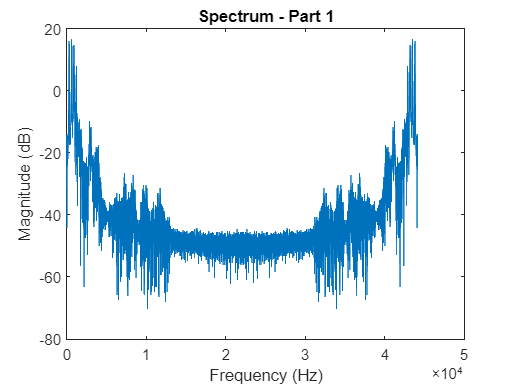

fund_freq = 648.2700

y9 = 6.7680

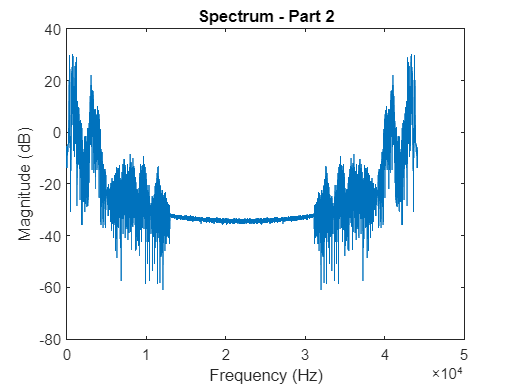

fund_freq = 767.3400

y9 = 31.7360

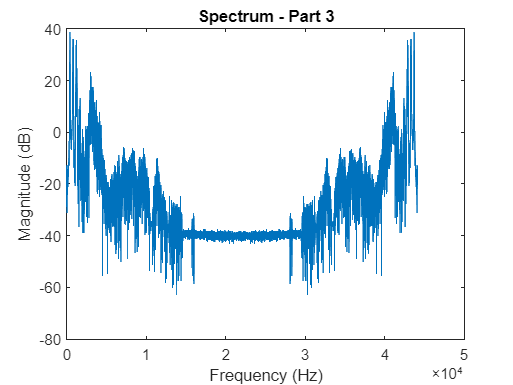

fund_freq = 418.9500

y9 = 85.2044

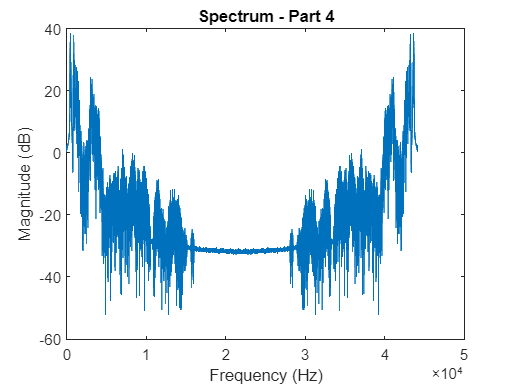

fund_freq = 507.1500

y9 = 83.5453

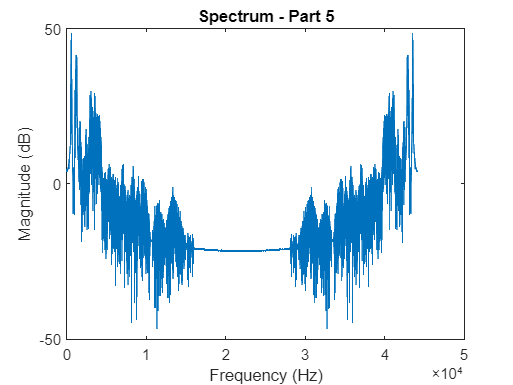

fund_freq = 588.7350

y9 = 269.6901

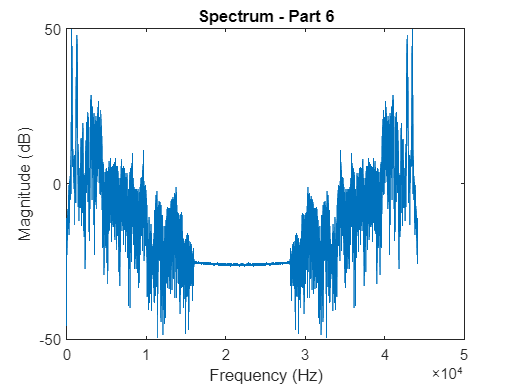

fund_freq = 621.8100

y9 = 312.1373

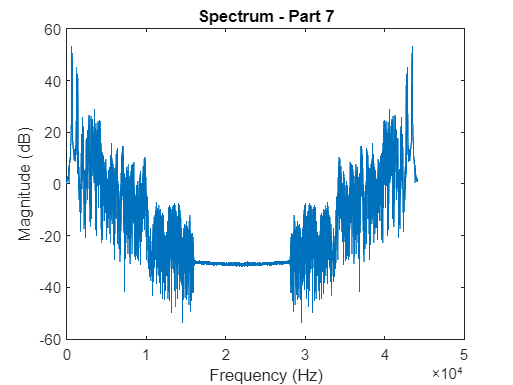

fund_freq = 621.8100

y9 = 453.0416

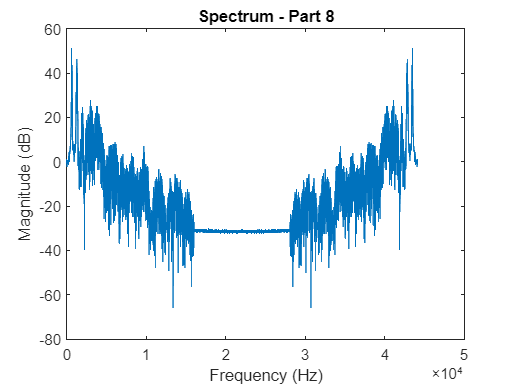

fund_freq = 624.0150

y9 = 354.0938

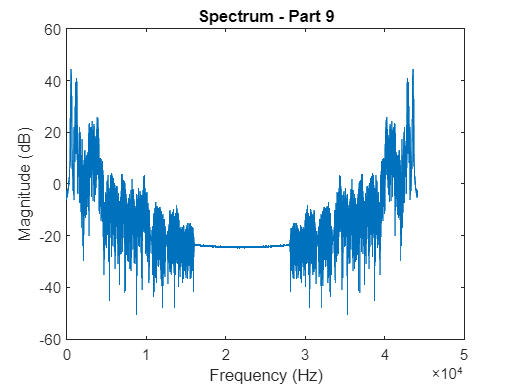

fund_freq = 544.6350

y9 = 168.6935

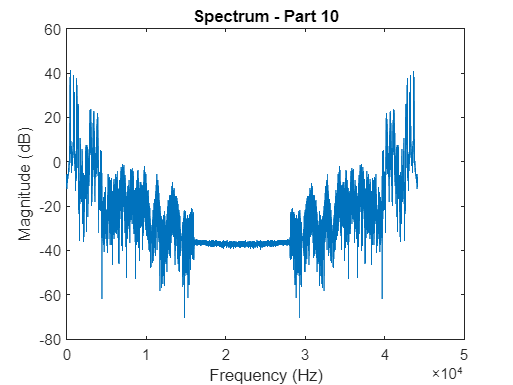

fund_freq = 482.8950

y9 = 112.2882

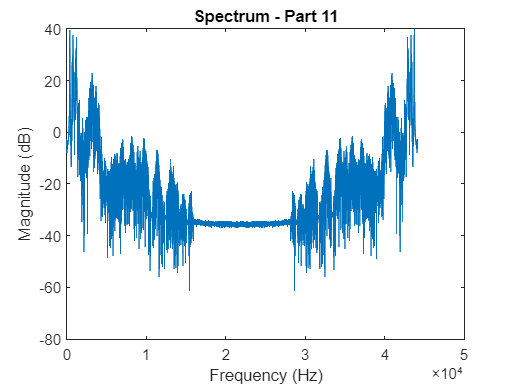

fund_freq = 403.5150

y9 = 96.2621

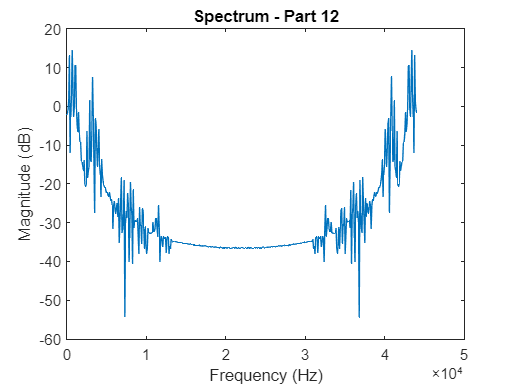

fund_freq = 705.6000

y9 = 5.3516

% Load the audio file
[y, fs] = audioread('Opera.wav');

% Number of samples per figure (20000 samples)
samples_per_figure = 20000;

% Calculate the number of figures
num_figures = ceil(length(y) / samples_per_figure);

for i = 1:num_figures
    % Define the start and end indices for the current chunk
    start_idx = (i - 1) * samples_per_figure + 1;
    end_idx = min(i * samples_per_figure, length(y));
    
    % Extract the current chunk
    chunk = y(start_idx:end_idx);
    
    % Compute the spectrum of the current chunk
    spectrum = abs(fft(chunk));
    
    % Define the frequency axis for the spectrum
    f = (0:length(chunk) - 1) * fs / length(chunk);
    
    % Plot the spectrum
    figure;
    plot(f, 20*log10(spectrum));
    title(['Spectrum - Part ', num2str(i)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    [y9,id1] = max(spectrum);
    fund_freq = f(id1)
    y9
end